% =========================================================================
% DIAGNÓSTICO DE MAPEO: EKF SLAM + Ajustes Geométricos y Log-Odds
% =========================================================================
clear; clc; close all;

%% 0. CONFIGURACIÓN DEL TEST
USAR_ESTIMACION_EKF = true;  % 'true' usa el EKF. 'false' usa GT u Odom pura.
USAR_GROUND_TRUTH   = false; % Solo aplica si USAR_ESTIMACION_EKF es 'false'

%% 1. Cargar el archivo ROSBAG
filePath = 'mir_basics_20251210_114529.bag'; % Reemplaza con tu archivo
disp('Abriendo archivo rosbag...');

Abriendo archivo rosbag...


bag = rosbag(filePath);

bagOdom = select(bag, 'Topic', '/odom');
bagScan = select(bag, 'Topic', '/scan');
bagGT   = select(bag, 'Topic', '/base_pose_ground_truth');

time_odom = bagOdom.MessageList.Time;
time_scan = bagScan.MessageList.Time;
time_gt   = bagGT.MessageList.Time;

disp('Leyendo mensajes del rosbag...');

Leyendo mensajes del rosbag...


odomMsgs = readMessages(bagOdom, 'DataFormat', 'struct');
scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');
gtMsgs   = readMessages(bagGT, 'DataFormat', 'struct');

%% 1.1 Extraer y Alinear Poses Iniciales
total_scan_msgs = length(scanMsgs);

% --- Alinear Ground Truth ---
[~, first_gt_idx] = min(abs(time_gt - time_scan(1)));
start_gt_pos = [gtMsgs{first_gt_idx}.Pose.Pose.Position.X, gtMsgs{first_gt_idx}.Pose.Pose.Position.Y];
start_gt_yaw = quat2yaw_local(gtMsgs{first_gt_idx}.Pose.Pose.Orientation);

% --- Alinear Odometría ---
[~, first_odom_idx] = min(abs(time_odom - time_scan(1)));
start_odom_pos = [odomMsgs{first_odom_idx}.Pose.Pose.Position.X, odomMsgs{first_odom_idx}.Pose.Pose.Position.Y];
start_odom_yaw = quat2yaw_local(odomMsgs{first_odom_idx}.Pose.Pose.Orientation);

%% 2. Inicialización del Mapa de Ocupación Log-Odds
map_res = 0.05; % Resolución de 10 cm
x_min = -20; x_max = 20; 
y_min = -20; y_max = 20;
cols = round((x_max - x_min) / map_res);
rows = round((y_max - y_min) / map_res);

log_odds_map = zeros(rows, cols); 

p_occ = 0.98;  % Umbral agresivo para paredes
p_free = 0.3;  % Limpieza de espacio libre
l_occ = log(p_occ / (1 - p_occ));
l_free = log(p_free / (1 - p_free));

l_max = 10;
l_min = -10;

trajectory_test = zeros(total_scan_msgs, 3);

%% 2.1. INICIALIZACIÓN DEL EKF
% Vector de estado inicial [x; y; theta]
mu = [0; 0; 0]; 
% Matriz de covarianza inicial
Sigma = diag([0.01, 0.01, 0.01]); 
% Ruido del proceso (Odometría)
%R = diag([0.001, 0.001, 0.001]); %NO HUBO CAMBIO
R = diag([0.05, 0.05, 0.02]); 
%R = diag([0.1, 0.1, 0.05]); %Aumentado para desconfiar de las ruedas, NO HUBO CAMBIO

% Variables para calcular el delta de odometría
prev_odom_x = 0; prev_odom_y = 0; prev_odom_yaw = 0;

%% 3. Bucle Principal de Construcción de Mapa
disp('Iniciando proceso de SLAM / Mapeo...');

Iniciando proceso de SLAM / Mapeo...



for i = 1:total_scan_msgs
    current_time = time_scan(i);
    scan = scanMsgs{i};

    % --- EXTRAER ODOMETRÍA ACTUAL ---
    [~, idx_odom] = min(abs(time_odom - current_time));
    msg_odom = odomMsgs{idx_odom};
    curr_odom_x = msg_odom.Pose.Pose.Position.X - start_odom_pos(1);
    curr_odom_y = msg_odom.Pose.Pose.Position.Y - start_odom_pos(2);
    yaw_raw = quat2yaw_local(msg_odom.Pose.Pose.Orientation);
    curr_odom_yaw = wrapToPi(yaw_raw - start_odom_yaw);

    % =====================================================================
    % --- A. ESTIMACIÓN DE POSE (EKF SLAM O REFERENCIAS DIRECTAS) ---
    % =====================================================================
    if USAR_ESTIMACION_EKF
        if i == 1
            % 1. EKF PREDICCIÓN
            % Primera iteración: inicializar prev_odom
            prev_odom_x = curr_odom_x;
            prev_odom_y = curr_odom_y;
            prev_odom_yaw = curr_odom_yaw;
        else
            % 1. EKF: PREDICCIÓN (Usando el modelo cinemático y la odometría)
            delta_rot1 = wrapToPi(atan2(curr_odom_y - prev_odom_y, curr_odom_x - prev_odom_x) - prev_odom_yaw);
            delta_trans = sqrt((curr_odom_x - prev_odom_x)^2 + (curr_odom_y - prev_odom_y)^2);
            delta_rot2 = wrapToPi(curr_odom_yaw - prev_odom_yaw - delta_rot1);

            % Actualizar la media estimada (mu)
            mu(1) = mu(1) + delta_trans * cos(mu(3) + delta_rot1);
            mu(2) = mu(2) + delta_trans * sin(mu(3) + delta_rot1);
            mu(3) = wrapToPi(mu(3) + delta_rot1 + delta_rot2);

            % Jacobiano del modelo de movimiento (G)
            G = [1, 0, -delta_trans * sin(mu(3) + delta_rot1);
                 0, 1,  delta_trans * cos(mu(3) + delta_rot1);
                 0, 0,  1];

            % Actualizar Covarianza (Sigma)
            Sigma = G*Sigma * G' + R;

            % Actualizar odometría previa para el siguiente ciclo
            prev_odom_x = curr_odom_x;
            prev_odom_y = curr_odom_y;
            prev_odom_yaw = curr_odom_yaw;

            % -------------------------------------------------------------
            % 2. EKF: CORRECCIÓN (UPDATE)
            % 
            % Si usas landmarks o scan matching, calcula la ganancia de 
            % Kalman (K), el error (z - h) y actualiza mu y Sigma.
            % -------------------------------------------------------------
            % H = ...
            % K = Sigma * H' * inv(H * Sigma * H' + Q);
            % mu = mu + K * (z - z_pred);
            % Sigma = (eye(3) - K * H) * Sigma;
            % -------------------------------------------------------------

            



        end
        
        % Asignar la pose estimada por el EKF para construir el mapa
        rob_x = mu(1);
        rob_y = mu(2);
        rob_yaw = mu(3);

    else
        % Modo de prueba original (Ground Truth u Odometría cruda)
        if USAR_GROUND_TRUTH
            [~, idx_gt] = min(abs(time_gt - current_time));
            msg_gt = gtMsgs{idx_gt};
            rob_x = msg_gt.Pose.Pose.Position.X - start_gt_pos(1);
            rob_y = msg_gt.Pose.Pose.Position.Y - start_gt_pos(2);
            yaw_raw_gt = quat2yaw_local(msg_gt.Pose.Pose.Orientation);
            rob_yaw = wrapToPi(yaw_raw_gt - start_gt_yaw);
        else
            rob_x = curr_odom_x;
            rob_y = curr_odom_y;
            rob_yaw = curr_odom_yaw;
        end
    end
    
    trajectory_test(i, :) = [rob_x, rob_y, rob_yaw];

  
    % --- B. AJUSTES GEOMÉTRICOS DEL SENSOR (TF) ---

    laser_offset_x   = 0.4296;    
    laser_offset_y   = 0.2358;    
    laser_offset_yaw = 0.7854;    
    invertir_angulos = 1;      
    
    laser_x = rob_x + laser_offset_x * cos(rob_yaw) - laser_offset_y * sin(rob_yaw);
    laser_y = rob_y + laser_offset_x * sin(rob_yaw) + laser_offset_y * cos(rob_yaw);
    laser_yaw = wrapToPi(rob_yaw + laser_offset_yaw);
    
    % =====================================================================
    % --- C y D. PROCESAMIENTO Y ACTUALIZACIÓN DE MAPA MEJORADO ---
    % =====================================================================
    all_ranges = double(scan.Ranges);
    angle_min = double(scan.AngleMin);
    angle_inc = double(scan.AngleIncrement);
    all_angles = angle_min + (0:length(all_ranges)-1)' * angle_inc;
    
    range_min = double(scan.RangeMin);
    r_max_mapping = 7.0; 
    
    laser_x_grid = round((laser_x - x_min) / map_res) + 1;
    laser_y_grid = round((laser_y - y_min) / map_res) + 1;
    
    for k = 1:length(all_ranges)
        r = all_ranges(k);
        a = all_angles(k);
        
        if isnan(r) || r < range_min
            continue;
        end
        
        es_impacto_valido = isfinite(r) && r <= r_max_mapping;
        r_trazado = min(r, r_max_mapping); 
        
        end_x = laser_x + r_trazado * cos(laser_yaw + (a * invertir_angulos));
        end_y = laser_y + r_trazado * sin(laser_yaw + (a * invertir_angulos));
        
        end_x_grid = round((end_x - x_min) / map_res) + 1;
        end_y_grid = round((end_y - y_min) / map_res) + 1;
        
        [ray_x, ray_y] = get_ray_cells(laser_x_grid, laser_y_grid, end_x_grid, end_y_grid);
        
        valid_ray_idx = ray_x > 0 & ray_x <= cols & ray_y > 0 & ray_y <= rows;
        ray_x = ray_x(valid_ray_idx);
        ray_y = ray_y(valid_ray_idx);
        
        if isempty(ray_x); continue; end
        
        lin_idx = sub2ind([rows, cols], ray_y, ray_x);
        
        if es_impacto_valido
            if length(lin_idx) > 1
                log_odds_map(lin_idx(1:end-1)) = log_odds_map(lin_idx(1:end-1)) + l_free;
            end
            log_odds_map(lin_idx(end)) = log_odds_map(lin_idx(end)) + l_occ;
        else
            log_odds_map(lin_idx) = log_odds_map(lin_idx) + l_free;
        end
    end

    if mod(i, 200) == 0
        fprintf('Procesados %d de %d scans...\n', i, total_scan_msgs);
    end
end

Procesados 200 de 10003 scans...
Procesados 400 de 10003 scans...
Procesados 600 de 10003 scans...
Procesados 800 de 10003 scans...
Procesados 1000 de 10003 scans...
Procesados 1200 de 10003 scans...
Procesados 1400 de 10003 scans...
Procesados 1600 de 10003 scans...
Procesados 1800 de 10003 scans...
Procesados 2000 de 10003 scans...
Procesados 2200 de 10003 scans...
Procesados 2400 de 10003 scans...
Procesados 2600 de 10003 scans...
Procesados 2800 de 10003 scans...
Procesados 3000 de 10003 scans...
Procesados 3200 de 10003 scans...
Procesados 3400 de 10003 scans...
Procesados 3600 de 10003 scans...
Procesados 3800 de 10003 scans...
Procesados 4000 de 10003 scans...
Procesados 4200 de 10003 scans...
Procesados 4400 de 10003 scans...
Procesados 4600 de 10003 scans...
Procesados 4800 de 10003 scans...
Procesados 5000 de 10003 scans...
Procesados 5200 de 10003 scans...
Procesados 5400 de 10003 scans...
Procesados 5600 de 10003 scans...
Procesados 5800 de 10003 scans...
Procesados 6000 de

disp('Mapeo Finalizado.');

Mapeo Finalizado.


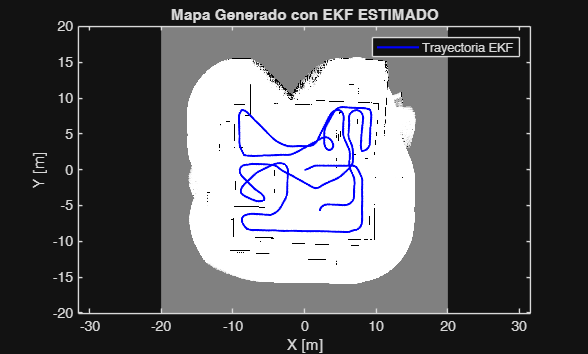


%% 4. Visualización
log_odds_map = max(min(log_odds_map, l_max), l_min);
prob_map = 1 - (1 ./ (1 + exp(log_odds_map)));

figure('Name', 'Mapeo con EKF SLAM Resultante', 'NumberTitle', 'off');
imagesc([x_min x_max], [y_min y_max], 1 - prob_map); 
colormap(gray); 
axis equal xy; 
hold on;
plot(trajectory_test(:,1), trajectory_test(:,2), 'b-', 'LineWidth', 1.5);

if USAR_ESTIMACION_EKF
    title('Mapa Generado con EKF ESTIMADO');
    legend('Trayectoria EKF');
elseif USAR_GROUND_TRUTH
    title('Mapa Generado con GROUND TRUTH (Ajustes de Sensor)');
    legend('Trayectoria GT', 'Color', 'r');
else
    title('Mapa Generado con ODOMETRÍA PURA (Ajustes de Sensor)');
    legend('Trayectoria Odometría');
end
xlabel('X [m]'); ylabel('Y [m]');


%% ========================================================================
% FUNCIONES AUXILIARES
% =========================================================================
function [x, y] = get_ray_cells(x1, y1, x2, y2)
    n_points = max(abs(x2 - x1), abs(y2 - y1)) + 1;
    x = round(linspace(x1, x2, n_points));
    y = round(linspace(y1, y2, n_points));
end

function yaw = quat2yaw_local(q)
    yaw = atan2(2*(q.W*q.Z + q.X*q.Y), 1 - 2*(q.Y^2 + q.Z^2));
end